## Example of 2 sessions for mouse 9041

electrode_position=[0 -1.2 -0.6 0;2 -2.8 0.05 0;3 -1.2 0.7 0;5 -2.8 1.35 0;26 -1.2 -3.2 0;28 -2.8 -2.55 0;29 -1.2 -1.9 0;31 -2.8 -1.25 0];
Opto_Ch=38;

existingFigs = findall(0, 'Type', 'figure');
basepath='D:\MULTI_EEG_preprocessing\9041\9041_headfixed_250124_155029'

basepath = 'D:\MULTI_EEG_preprocessing\9041\9041_headfixed_250124_155029'


[Animal9041a.ChangeDeltaPower,condSpec,wspec_freqs,Channels]=Multi_eeg_LFP_processing(basepath,Opto_Ch,electrode_position);

Data already processed...


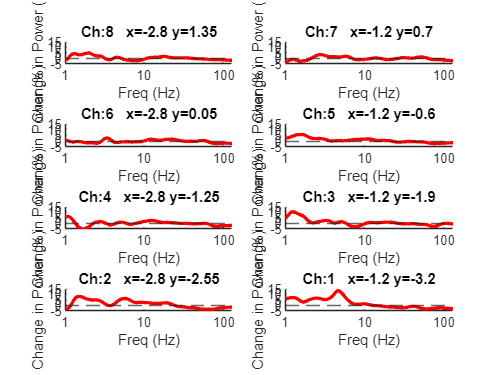

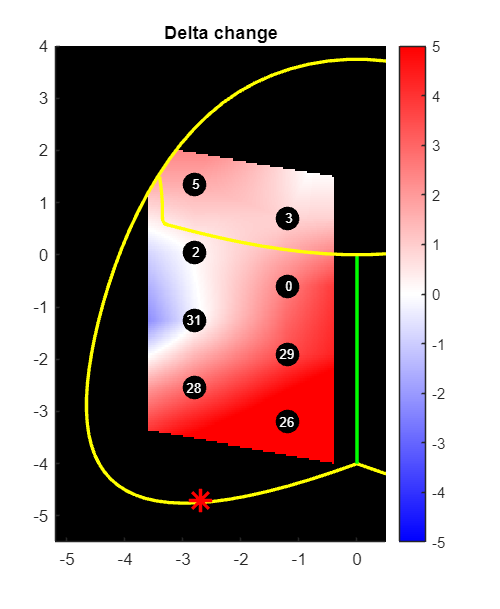

[Animal9041a.powerSpec]=plotPowerspec(wspec_freqs,condSpec,Channels,electrode_position);
[Animal9041a.elec_map]=MeshGrid_representation(Channels,Animal9041a.ChangeDeltaPower,electrode_position);
Animal9041a.AnimalID='9041a';

allFigs = findall(0, 'Type', 'figure');
newFigs = setdiff(allFigs, existingFigs);  % Only the new ones!
for i = 1:numel(newFigs)
    fig = newFigs(i);
    figure(fig);   
    filename = sprintf('%s_Figure%d.png', '9041a', i);
    exportgraphics(fig, fullfile(basepath, filename), 'Resolution', 300);
    % close(fig);
end

existingFigs = findall(0, 'Type', 'figure');
basepath='D:\MULTI_EEG_preprocessing\9041\9041_headfixed_250128_153223'

basepath = 'D:\MULTI_EEG_preprocessing\9041\9041_headfixed_250128_153223'


[Animal9041b.ChangeDeltaPower,condSpec,wspec_freqs,Channels]=Multi_eeg_LFP_processing(basepath,Opto_Ch,electrode_position);

Data already processed...


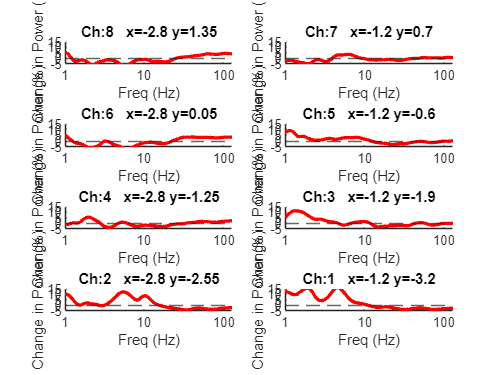

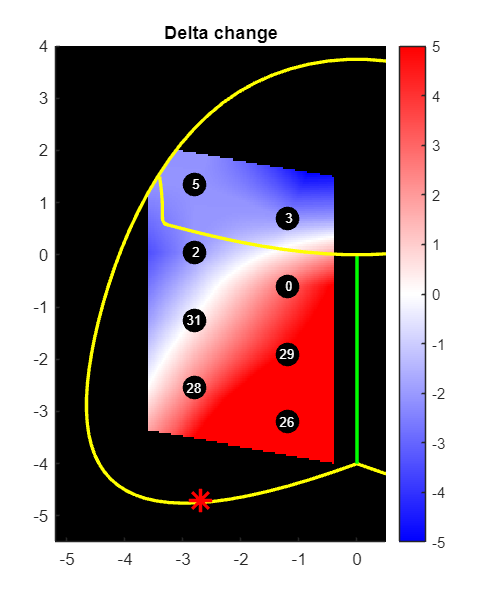

[Animal9041b.powerSpec]=plotPowerspec(wspec_freqs,condSpec,Channels,electrode_position);
[Animal9041b.elec_map]=MeshGrid_representation(Channels,Animal9041b.ChangeDeltaPower,electrode_position);
Animal9041b.AnimalID='9041b';

allFigs = findall(0, 'Type', 'figure');
newFigs = setdiff(allFigs, existingFigs);  % Only the new ones!
for i = 1:numel(newFigs)
    fig = newFigs(i);
    figure(fig);   
    filename = sprintf('%s_Figure%d.png', '9041b', i);
    exportgraphics(fig, fullfile(basepath, filename), 'Resolution', 300);
    % close(fig);
end

## All Animals analysis

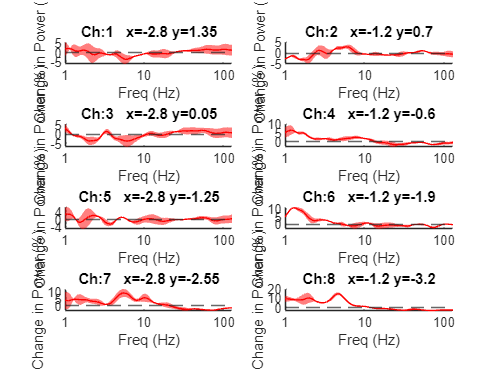

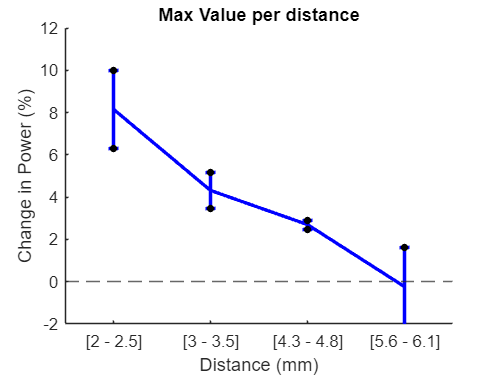

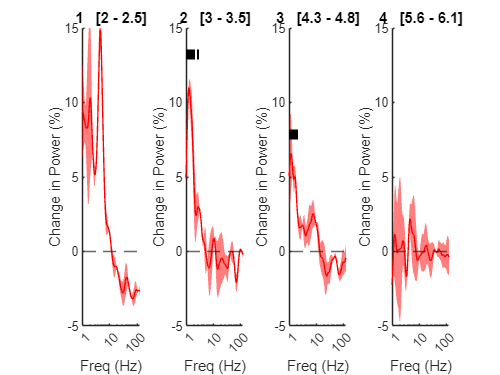

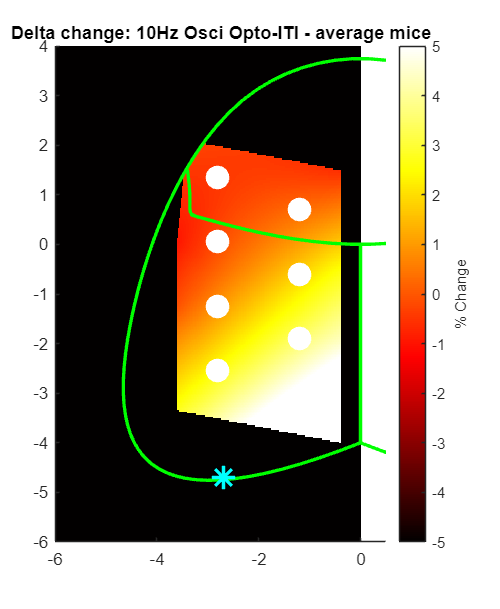

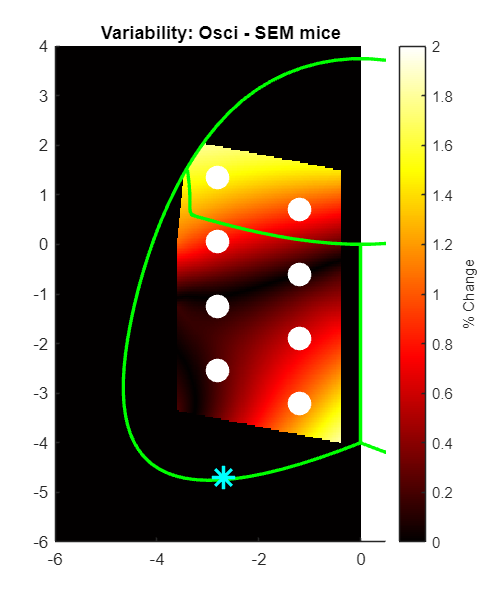

existingFigs = findall(0, 'Type', 'figure');
animals = [Animal9041a,Animal9041b];%to add all animals

basepath='D:\MULTI_EEG_preprocessing';
cd(basepath)
% save("All_Animals_Spider","animals", "wspec_freqs")
plotPowerspec_Allmice(wspec_freqs,animals)

[MaxChangeDELTA,NormSpec]=MaxChplotPowerspec_Allmice(wspec_freqs,animals);
MeshGrid_representation_Allmice(animals,[-2.7, -4.7])

allFigs = findall(0, 'Type', 'figure');
newFigs = setdiff(allFigs, existingFigs);  % Only the new ones!
for i = 1:numel(newFigs)
    fig = newFigs(i);
    figure(fig);   
    filename = sprintf('%s_Figure%d.png', 'Average_All_Mice_ProxCh', i);
    exportgraphics(fig, fullfile(basepath, filename), 'Resolution', 300);
    % close(fig);
end

function [ChangeDeltaPower,condSpec,wspec_freqs,Channels]=Multi_eeg_LFP_processing(basepath,Opto_Ch,electrode_position)
% see original script Multi_eeg_LFP

basename=bz_BasenameFromBasepath(basepath);
cd(basepath)
try load([basename,'.PowerSpec_OptoInt.mat'])
disp('Data already processed...')
catch


load([basename,'.sessionInfo.mat'])
Channels=sessionInfo.channels(~ismember(sessionInfo.channels,sessionInfo.badchannels) & ismember(sessionInfo.channels,electrode_position));

passband=[1 4];%delta

    if exist(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespecReref.lfp.mat"),'file')
       load(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespecReref.lfp.mat"))
    else

    %% Extract LFP

    [lfp] = bz_GetLFP(Channels); %in sec
    lfp.data = lfp.data - median(lfp.data,2);%MedianRef

    wavespec = bz_WaveSpec(lfp,'chanID',0:31,'showprogress',true,'saveMat',true,...
        'MatNameExtraText','Reref','saveMatPath',basepath,'downsampleout',lfp.samplingRate/10);
    end

%% Extract Intervals OPTO and ITI %
[Opto_lfp] = bz_GetLFP(Opto_Ch); %in sec

% Find intervals of stim
Signal_Opto=double(Opto_lfp.data);
Time_Opto=Opto_lfp.timestamps;

[int1,in1] = Threshold([Time_Opto,Signal_Opto],'>',1000);%used min because of artefact

[Opto_Int,~]=ConsolidateIntervals(int1,'epsilon',2);%if oscillations - check with lower stim
Opto_Int(:,3)=[Opto_Int(:,2)-Opto_Int(:,1)];

artefact_idx=find(Opto_Int(:,3)<=28); %block should be ~30sec - in case of artefact, remove it
Opto_Int(artefact_idx,:)=[];

if size(Opto_Int,1)>60
    Opto_Int(end,:)=[];
end

DelOpto=[1;find(diff(Opto_Int(:,1))>1000)+1];%remove first opto interval after spont - might change behavior of mouse
Opto_Int(DelOpto,:)=[];

[Tot_Opto_Int,~]=ConsolidateIntervals(Opto_Int(:,1:2),'epsilon',40);
Spont_Int=SubtractIntervals([1 Time_Opto(end)],Tot_Opto_Int);

% % Opto_Int=[Opto_Int(11:21,:);Opto_Int(31:40,:);Opto_Int(51:60,:)];%01/28/25

for i=1:size(Opto_Int,1)
    if i==size(Opto_Int,1)
    ITI_Int(i,:)=[Opto_Int(i,2),Opto_Int(i,2)+30,30];
    else
    ITI_Int(i,:)=([Opto_Int(i,2),Opto_Int(i+1,1),(Opto_Int(i+1,1)-Opto_Int(i,2))]);
    end

end

Inter_stim=ITI_Int(:,3)>60;
ITI_Int(Inter_stim,2)=ITI_Int(Inter_stim,1)+30;
ITI_Int(Inter_stim,3)=30;


% do the same for flat vs oscil opto intervals discriminate between flat and oscillatory opto
[Flat_int,~] = Threshold([Time_Opto,Signal_Opto],'>',1000,'min',10);

DelOpto=[1;find(diff(Flat_int(:,1))>1000)+1];%remove first flat opto interval after spont - might change behavior of mouse
Flat_int(DelOpto,:)=[];

AA=SubtractIntervals(Opto_Int(:,1:2),Flat_int);
Osci_int=SubtractIntervals(AA,Flat_int);

% optoInts.Opto_Int=[Opto_Int(:,1)+1 Opto_Int(:,2)];

optoInts.Flat_Opto_int=[Flat_int(:,1)+1 Flat_int(:,1)+11];%avoid potential desensitization
optoInts.Osci_Opto_int=[Osci_int(:,1)+1 Osci_int(:,1)+29];
optoInts.Flat_ITI_int=[Flat_int(:,2)+1 Flat_int(:,2)+11];
optoInts.Osci_ITI_int=[Osci_int(:,2)+1 Osci_int(:,2)+29];

optoInts.Opto_Int=[sort([optoInts.Flat_Opto_int;optoInts.Osci_Opto_int])];
optoInts.ITI_Int=[sort([optoInts.Flat_ITI_int;optoInts.Osci_ITI_int])];

try
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate;

optoInts.NREMStim = IntersectIntervals(stateInts.NREM, optoInts.Flat_Opto_int);
optoInts.NREMSpont = IntersectIntervals(stateInts.NREM, Spont_Int);
end

wspec=wavespec;

%Determine channels analyzed that fit with the recording
co=find(ismember(wspec.channels,Channels));

conditions = fieldnames(optoInts);
for i=1:numel(conditions)
    [~, condmask] = RestrictInts(wspec.timestamps, optoInts.(conditions{i})(:,1:2));
    % % % % condSpec.(conditions{i}) = nanmean(nanmean(abs(wspec.data(condmask,:,:)),1),3) ...
    % % % %     ./ trapz(wspec.freqs, nanmean(nanmean(abs(wspec.data(condmask,:,:)),1),3));
    condSpec.(conditions{i}) = squeeze(nanmean(abs(wspec.data(condmask,:,co)),1)) ...
        ./ trapz(wspec.freqs, squeeze(nanmean(abs(wspec.data(condmask,:,co)),1)));
    % condSpec.(conditions{i}) = squeeze(nanmean(abs(wspec.data(condmask,:,:)),1));        
    for jj=1:numel(co)
    if any(isnan(condSpec.(conditions{i})(jj)))
    condDelta.(conditions{i})(jj) = nan;
    else
    condDelta.(conditions{i})(jj) = bandpower(condSpec.(conditions{i})(:,jj), wspec.freqs,passband,'psd');
    end
    end
end

% ChangePower=(condDelta.Opto_Int-condDelta.ITI_Int)';
ChangeDeltaPower.All=((condDelta.Opto_Int./condDelta.ITI_Int)*100-100)';
ChangeDeltaPower.Osci=((condDelta.Osci_Opto_int./condDelta.Osci_ITI_int)*100-100)';
ChangeDeltaPower.Flat=((condDelta.Flat_Opto_int./condDelta.Flat_ITI_int)*100-100)';

try
ChangeDeltaPower.FlatNREM=((condDelta.NREMStim./condDelta.NREMSpont)*100-100)';
end

wspec_freqs=wspec.freqs;%dependence for other functions and don't want to reload wavespec because long and heavy
% save (basename + ".PowerSpec_OptoInt.mat","ChangeDeltaPower","condSpec","optoInts","wspec_freqs","Channels")
end
end

function [powerSpec]=plotPowerspec(wspec_freqs,condSpec,Channels,electrode_position)


Fiber_Pos=[-2.7, -4.7];

for i=1:size(electrode_position,1)
electrode_position(i,4)=sqrt((electrode_position(i,2) - Fiber_Pos(1))^2 + (electrode_position(i,3) - Fiber_Pos(2))^2);
end

[~,b]=sort(electrode_position(:,4));
electrode_position=electrode_position(b,:);

opto='Osci_Opto_int';
iti='Osci_ITI_int';
O=condSpec.(opto);
I=condSpec.(iti);   
powerSpec.(opto)=O;
powerSpec.(iti)=I;
powerSpec.([opto,'Normalized'])=(O./(I))*100-100;

figure
for ii=1:size(electrode_position,1)
    try
    Ch=find(Channels==electrode_position(ii,1));

    subplot(4,2,size(electrode_position,1)-ii+1),hold on;
    plot(wspec_freqs, (O(:,Ch)./(I(:,Ch)))*100-100,'r','LineWidth',2)
    set(gca, 'xscale','log')
    xticks([1 10 100])
    xticklabels([1 10 100])
    xlabel('Freq (Hz)')
    ylabel('Change in Power (%)')
    title(['Ch:',num2str(ii), '   x=',num2str(electrode_position(ii,2)),' y=',num2str(electrode_position(ii,3))])
    yline(0,'--')
    ylim([-5 15])
    end
end

end

function [elec_map]=MeshGrid_representation(Channels,ChangeDeltaPower,electrode_position)

Fiber_Pos=[-2.7, -4.7];

for i=1:size(electrode_position,1)
electrode_position(i,4)=sqrt((electrode_position(i,2) - Fiber_Pos(1))^2 + (electrode_position(i,3) - Fiber_Pos(2))^2);
end

% Map according to channels used for lfp - working channels
for i=1:size(Channels,2)
Pos=find(electrode_position(:,1) == Channels(i));
elec_map(i,:)=electrode_position(Pos,:);
end

% % % Interpolate intensity values over the grid
% % Zq = griddata(elec_map(:,1), elec_map(:,2), elec_map(:,3), Xq, Yq, 'natural');
% Create a mask using the boundary
x_grid = linspace(-6, 0, 300);  % Define grid based on electrode positions
y_grid = linspace(-6, 6, 300);
[grid_X, grid_Y] = meshgrid(x_grid, y_grid);


boundariesElec=[
-3.6          2.1
-0.4          1.5
-0.4         -0.6
-0.4         -1.9
-0.4           -4
-3.6        -3.35
-3.6        -1.25
-3.6         0.05
-3.6          2.1];

x_grid = linspace(-6, 0, 300);  % Define grid based on electrode positions
y_grid = linspace(-6, 6, 300);
[grid_X, grid_Y] = meshgrid(x_grid, y_grid);

% Interpolate over full grid
F = scatteredInterpolant(elec_map(:,2), elec_map(:,3), ChangeDeltaPower.Osci, 'natural', 'linear');
Zq_Osci = F(grid_X, grid_Y);

% Set outside values to NaN directly via polygon
[in_boundary, ~] = inpolygon(grid_X, grid_Y, boundariesElec(:,1), boundariesElec(:,2));
Zq_Osci(~in_boundary) = NaN;


% Skull coordinates
x_coords = [0 4 4.5 2.2 -2.2 -4.5 -4];
y_coords = [-4 -4.5 -1.5 3 3 -1.5 -4.5];

% Close the shape by adding the first point to the end
x_coords = [x_coords, x_coords(1)];
y_coords = [y_coords, y_coords(1)];

% Parameterize the coordinates (for smoothing)
t = 1:length(x_coords);  % Simple parameterization

% Use spline interpolation for smoothing the curve
t_fine = linspace(1, length(x_coords), 100);  % Fine grid for interpolation
x_smooth = spline(t, x_coords, t_fine);
y_smooth = spline(t, y_coords, t_fine);

[in_boundary, ~] = inpolygon(grid_X, grid_Y, x_smooth, y_smooth);

% Mask the interpolated intensity values

Zq_Osci(~in_boundary) = NaN;

% Coordinates for the suture bregma
xCurveLine = [-3.4 -3.35 -3.3 -3.21 -3 0 3 3.21 3.3 3.35 3.4];
yCurveLine = [1.5 0.8 0.6 0.56 0.5 0 0.5 0.56 0.6 0.8 1.5];

% Fine grid for the curve (to make it smooth)
t = linspace(1, length(xCurveLine), 100); 
x_smooth_suture = spline(1:length(xCurveLine), xCurveLine, t);
y_smooth_suture = spline(1:length(yCurveLine), yCurveLine, t);

% Plot heatmap

figure('Position', [100, 100, 552, 672]);
h=imagesc(x_grid, y_grid, Zq_Osci,[-5,5]);
axis xy;
% colormap hot;
colormap redblue;
set(h, 'AlphaData', ~isnan(Zq_Osci)); % NaN => transparent
set(gca, 'Color', 'k'); % black background
colorbar
title('Delta change');

hold on
plot(x_smooth, y_smooth, 'y-', 'LineWidth', 2);
hold on
plot([0,0],[-4 0],'g','linewidth',2)
hold on;
plot(x_smooth_suture, y_smooth_suture, 'y-', 'LineWidth', 2); 
hold on
scatter(elec_map(:,2), elec_map(:,3), 200, 'filled', 'k');  % Plot the original electrode locations
hold on
scatter(Fiber_Pos(1),Fiber_Pos(2),200,'*','r', 'linewidth',2)
box off
xlim([-5.2 0.5])
ylim([-5.5 4])

hold on
text(elec_map(:,2), elec_map(:,3),num2str(elec_map(:,1)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment','middle','Color','w','FontSize',8);
end

function plotPowerspec_Allmice(wspec_freqs,animals)

%Plot powerspec according to channels
O='Osci_Opto_int';
I='Osci_ITI_int';  
N=[O,'Normalized'];

ELEC=[-1.20000000000000	-0.600000000000000	4.36577599058862
	-2.80000000000000	0.0500000000000000	4.75105251496971
	-1.20000000000000	0.700000000000000	5.60446250768082
	-2.80000000000000	1.35000000000000	6.05082638984131
	-1.20000000000000	-3.20000000000000	2.12132034355964
	-2.80000000000000	-2.55000000000000	2.15232432500309
	-1.20000000000000	-1.90000000000000	3.17647603485372
	-2.80000000000000	-1.25000000000000	3.45144897108446];

[~,b]=sort(ELEC(:,3),'descend');
ELEC=ELEC(b,:);


figure

    for j=1:8
    opto=[];ITI=[];Normalized=[];
        xxx=ELEC(j,1);yyy=ELEC(j,2);

        for jj=1:numel(animals)
            try
            PosCh=find(animals(jj).elec_map(:,2)==ELEC(j,1) & animals(jj).elec_map(:,3)==ELEC(j,2));
            opto=[opto animals(jj).powerSpec.(O)(:,PosCh)];
            ITI=[ITI animals(jj).powerSpec.(I)(:,PosCh)];
            Normalized = [Normalized animals(jj).powerSpec.(N)(:,PosCh)];
            end
        end

    subplot(4,2,j),hold on;
    % hb=shadedErrorBar(wspec_freqs,mean(Normalized,2),std(Normalized,[],2,'omitnan')./sqrt(size(Normalized,2)));
    hb=shadedErrorBar(wspec_freqs,mean(Normalized,2),std(Normalized,[],2,'omitnan')./sqrt(sum(~isnan(Normalized), 2)));
    hb.mainLine.Color='r';
    hb.patch.FaceColor='r';
    hb.patch.FaceAlpha=0.5;
    set(hb.edge,'LineWidth',2,'LineStyle','none');

    set(gca, 'xscale','log')
    xticks([1 10 100])
    xticklabels([1 10 100])
    xlabel('Freq (Hz)')
    ylabel('Change in Power (%)')
    title(['Ch:',num2str(j), '   x=',num2str(xxx),' y=',num2str(yyy)])
    yline(0,'--')
    end

end


function [MaxChangeDELTA,NormSpec]=MaxChplotPowerspec_Allmice(wspec_freqs,animals)

%Plot powerspec according to channels
O='Osci_Opto_int';
N=[O,'Normalized'];
MaxChangeDELTA=[];
XXX=[];
ELEC=[-1.20000000000000	-0.600000000000000	4.36577599058862
	-2.80000000000000	0.0500000000000000	4.75105251496971
	-1.20000000000000	0.700000000000000	5.60446250768082
	-2.80000000000000	1.35000000000000	6.05082638984131
	-1.20000000000000	-3.20000000000000	2.12132034355964
	-2.80000000000000	-2.55000000000000	2.15232432500309
	-1.20000000000000	-1.90000000000000	3.17647603485372
	-2.80000000000000	-1.25000000000000	3.45144897108446];

[~,b]=sort(ELEC(:,3));
ELEC=ELEC(b,:);

k=0;

figure
    for j=1:4
    ChangeDELTA=[];Normalized=[];
        if j==1
        xxx='[2 - 2.5]';
        elseif j==2
        xxx='[3 - 3.5]';   
        elseif j==3
        xxx='[4.3 - 4.8]'; 
        elseif j==4
        xxx='[5.6 - 6.1]';
        end

        for jj=1:numel(animals)
            try
            PosCh1=find(animals(jj).elec_map(:,2)==ELEC(j+k,1) & animals(jj).elec_map(:,3)==ELEC(j+k,2));
            catch
            PosCh1=[];
            end
            try
            PosCh2=find(animals(jj).elec_map(:,2)==ELEC(j+k+1,1) & animals(jj).elec_map(:,3)==ELEC(j+k+1,2));
            catch
            PosCh2=[];
            end


            if isempty(PosCh1)
                PosCh=PosCh2;
            elseif isempty(PosCh2)
                PosCh=PosCh1;
            elseif animals(jj).ChangeDeltaPower.Osci(PosCh1,1)<animals(jj).ChangeDeltaPower.Osci(PosCh2,1)
                PosCh=PosCh2;
            elseif animals(jj).ChangeDeltaPower.Osci(PosCh1,1)>animals(jj).ChangeDeltaPower.Osci(PosCh2,1)
                PosCh=PosCh1;
            end

            ChangeDELTA = [ChangeDELTA animals(jj).ChangeDeltaPower.Osci(PosCh,1)];
            Normalized = [Normalized animals(jj).powerSpec.(N)(:,PosCh)];

        end
        
        k=k+1;

    
    subplot(1,4,j),hold on;
    hb=shadedErrorBar(wspec_freqs,mean(Normalized,2),std(Normalized,[],2,'omitnan')./sqrt(sum(~isnan(Normalized), 2)));
    hb.mainLine.Color='r';
    hb.patch.FaceColor='r';
    hb.patch.FaceAlpha=0.5;
    set(hb.edge,'LineWidth',2,'LineStyle','none');

    set(gca, 'xscale','log')
    xticks([1 10 100])
    xticklabels([1 10 100])
    xlabel('Freq (Hz)')
    ylabel('Change in Power (%)')
    ylim([-5 15])
    title([num2str(j), '   ',(xxx)])
    yline(0,'--')
    
    MaxChangeDELTA=[MaxChangeDELTA,ChangeDELTA'];
    XXX{j}=xxx;
    NormSpec{j}=Normalized;
    Results_vs0=StatOnFreq(NormSpec{j});
    
    Signif=Results_vs0.Signif;
    hold on
    scatter(wspec_freqs(Signif),repelem(max(mean(Normalized,2))*1.2,size(Signif,2)),'|','k')

    end

    figure,hold on;
    errorbar([1:4],mean(MaxChangeDELTA,1),std(MaxChangeDELTA,[],1,'omitnan')./sqrt(sum(~isnan(MaxChangeDELTA), 1)),'b','LineWidth',2);
    xticks([1:4])
    xticklabels(XXX)
    xlabel('Distance (mm)')
    ylabel('Change in Power (%)')
    ylim([-2 12])
    xlim([0.5 4.5])
    title('Max Value per distance')
    yline(0,'--')
    hold on;
    scatter([1:4],MaxChangeDELTA,20,'black','filled')

end

function MeshGrid_representation_Allmice(animals,Fiber_Pos)

% Create a mask using the boundary
x_grid = linspace(-6, 0, 300);  % Define grid based on electrode positions
y_grid = linspace(-6, 4, 300);
[grid_X, grid_Y] = meshgrid(x_grid, y_grid);
% Skull coordinates
x_coords = [0 4 4.5 2.2 -2.2 -4.5 -4];
y_coords = [-4 -4.5 -1.5 3 3 -1.5 -4.5];

% Close the shape by adding the first point to the end
x_coords = [x_coords, x_coords(1)];
y_coords = [y_coords, y_coords(1)];

% Parameterize the coordinates (for smoothing)
t = 1:length(x_coords);  % Simple parameterization

% Use spline interpolation for smoothing the curve
t_fine = linspace(1, length(x_coords), 100);  % Fine grid for interpolation
x_smooth = spline(t, x_coords, t_fine);
y_smooth = spline(t, y_coords, t_fine);


% Coordinates for the suture bregma
xCurveLine = [-3.4 -3.35 -3.3 -3.21 -3 0 3 3.21 3.3 3.35 3.4];
yCurveLine = [1.5 0.8 0.6 0.56 0.5 0 0.5 0.56 0.6 0.8 1.5];

% Fine grid for the curve (to make it smooth)
t = linspace(1, length(xCurveLine), 100); 
x_smooth_suture = spline(1:length(xCurveLine), xCurveLine, t);
y_smooth_suture = spline(1:length(yCurveLine), yCurveLine, t);

for i=1:length(animals)

elec_map=animals(i).elec_map;
ChangeDeltaPower=animals(i).ChangeDeltaPower;

elec_map2= [0         -0.4         -0.6       4.3658
            2         -3.6         0.05       4.7511
            3         -0.4          1.5       5.6045
            5         -3.4         2.1       6.0508
           26         -0.4         -4       2.1213
           28         -3.6        -3.35       2.1523
           29         -0.4        -1.9       3.1765
           31         -3.6        -1.25       3.4514];

% b=find(ismember(elec_map2(:,1),elec_map(:,1)));%07/18/2025
b=find(ismember(round(elec_map2(:,4),2),round(elec_map(:,4),2)));
elec_map2=elec_map2(b,:);


% Interpolate intensity values over the grid
Zq_Osci{i} = griddata(elec_map2(:,2), elec_map2(:,3), ChangeDeltaPower.Osci, grid_X, grid_Y, 'natural');
% 
end

% Stack all matrices along a third dimension
stacked_Osci = cat(3, Zq_Osci{:});  % Result: 100 x 100 x N matrices (N = number of cells)

% Compute the mean across the 3rd dimension
Zq_Osci_mean = nanmean(stacked_Osci, 3);

% Compute the SEM across the 3rd dimension
Zq_Osci_sem = std(stacked_Osci, 0, 3,'omitnan')./ sqrt(size(stacked_Osci, 3));

[in_boundary, ~] = inpolygon(grid_X, grid_Y, x_smooth, y_smooth);

% Mask the interpolated intensity values
Zq_Osci_mean(~in_boundary) = NaN;
Zq_Osci_sem(~in_boundary) = NaN;

% Plot heatmap
LIM=[-5,5];
for i=1:2
    if i==1
        Z= Zq_Osci_mean;TITLE='Delta change: 10Hz Osci Opto-ITI - average mice';
    elseif i==2
        Z= Zq_Osci_sem;TITLE='Variability: Osci - SEM mice';
        LIM=[0,2];
    end

figure('Position', [100, 100, 552, 672]);
imagesc(x_grid, y_grid, Z,LIM);
axis xy;
colormap hot;
c=colorbar;
c.Label.String = '% Change';
title(TITLE);

hold on
plot(x_smooth, y_smooth, 'g-', 'LineWidth', 2);
hold on
plot([0,0],[-4 0],'g','linewidth',2)
hold on;
plot(x_smooth_suture, y_smooth_suture, 'g-', 'LineWidth', 2); 
hold on
scatter(elec_map(:,2), elec_map(:,3), 200, 'filled', 'w');  % Plot the original electrode locations
hold on
scatter(Fiber_Pos(1),Fiber_Pos(2),200,'*','c', 'linewidth',2)
box off
xlim([-6 0.5])
ylim([-6 4])

end
end

function Results_vs0=StatOnFreq(NORMSPEC)
MaxChangeDELTA = NORMSPEC';
nSubjects = size(MaxChangeDELTA,1);
nCond     = size(MaxChangeDELTA,2);
SUBJECT   = (1:nSubjects)';     % keep same name

%% Prepare long-format table
Obs = [];
for i = 1:nCond
    tmp.Subject = SUBJECT;
    tmp.Distance = repmat(i, nSubjects, 1);
    tmp.Value = MaxChangeDELTA(:,i);
    Obs = [Obs; struct2table(tmp)];
end
Obs.Distance = categorical(Obs.Distance);

%% Fit LME
lme = fitlme(Obs, 'Value ~ Distance + (1|Subject)');

% disp('--- Repeated-measures ANOVA via fitlme ---');
% anova(lme)

%% Post-hoc vs 0 using LME estimates
beta = fixedEffects(lme);                    % coefficients
COV  = lme.CoefficientCovariance;           % covariance matrix
DF   = lme.DFE;                              % degrees of freedom

tstat = nan(1,nCond);
p_raw = nan(1,nCond);

for i = 1:nCond
    L = zeros(1,length(beta));
    if i == 1
        L(1) = 1;  % intercept = distance 1
    else
        L(1) = 1;  % intercept
        L(i) = 1;  % distance i effect
    end
    tstat(i) = (L * beta) / sqrt(L * COV * L');       % t-stat
    p_raw(i) = 2 * (1 - tcdf(abs(tstat(i)), DF));    % two-sided
end

% Bonferroni correction
p_bonf = min(p_raw * nCond, 1);
signif = p_bonf < 0.05;

Results_vs0 = table((1:nCond)', mean(MaxChangeDELTA)', std(MaxChangeDELTA)'/sqrt(nSubjects)', ...
    tstat', p_raw', p_bonf', signif', ...
    'VariableNames', {'Distance','Mean','SEM','tstat','p_raw','p_bonf','Signif'});

% disp('--- Post-hoc vs 0 (two-sided, LME estimates) ---');
% disp(Results_vs0);
end
